# Probability: The Basics

**Suggested Prework**

[MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

You can use this script in a controls-only mode by selecting the **Hide code **  button or view the code by selecting the **Output inline**    button on the **View** tab of the MATLAB toolstrip.

## What is Probability?

### Subjective perspective

Subjective probability refers to an individual's belief, judgment, or experience about the chances of an outcome occurring. 

- What is the probability that your favorite football team will win the next World Cup?

- What are the chances that the cryptocurrency you invested in will go up in value next week?

Quantifying the chances of such events allows us to make sense of "randomness" and uncertainty. However, subjective probabilities can differ from person to person. While many individuals tend to naturally update their prior estimates in light of new evidence, a subjective perspective is often prone to biases and lack of consistency—other interpretations of probability attempt to be more coherent and objective.

### Classical definition–a priori

A random process (or experiment) has a fixed set of possible outcomes in the classical perspective. Each of these is equally likely to occur. The probability of an event is simply the fraction of all the outcomes that are favorable to the event.

Consider a deck of fifty-two playing cards. It contains cards belonging to the four suits shown below. Each suit has thirteen cards – nine numbered cards (2 through 10), three face cards (J,Q,K), and one ace (A). 

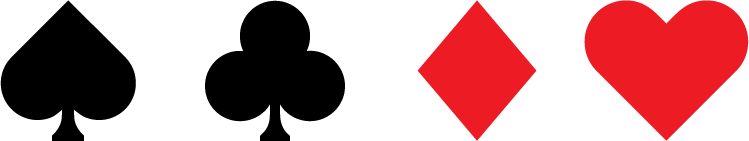

If you draw a single card at random from a well-shuffled deck, what is the probability of drawing the ace of clubs? Since there is only one ace of clubs in a deck of 52, the probability of the event is 1/52.

chanceEvent = "AceClubs";

**Task. **How many of the 52 possible outcomes are favorable to the selected `chanceEvent` event? Enter the number in the edit field for `favorableOutcomes`.

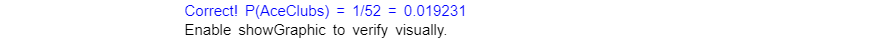

favorableOutcomes = 1;
totalOutcomes     = 52;
probability       = favorableOutcomes/totalOutcomes;
showGraphic       = false;
 
visualizeCards(chanceEvent,probability,showGraphic);

  **Try**

- Use the drop-down for `chanceEvent` to choose a random draw event. Calculate the probability of the selected event by counting the number of outcomes favorable to that event (`favorableOutcomes`) out of all the possible outcomes (`totalOutcomes`).

- Visually verify the number of favorable outcomes by using the check box to set `showGraphic` to `true`.

- Use the drop-down to compute the probabilities of the following events: a black card, a numbered card, and a black numbered card.

 ***Reflect***

- *Drawing a black card and drawing a numbered card from a well-shuffled deck are two independent events. How do their probabilities combine to get the probability of drawing a black (****and****) numbered card?*

- *Can you apply this definition to find the probability of landing on a 5 when you throw a fair die? How about if it is a weighted die with unknown weights? *

- *What are some other examples of a random experiment or a random process?*

- *Do most random processes have a countable number of possible outcomes? If not, what are some examples of other kinds of random processes or experiments?*

### Empirical definition–a posteriori, frequentist

The classical perspective makes two major assumptions:

- the elementary events in a random process are all *equally likely* to occur 

- there are a countably finite number of possible outcomes

These assumptions do not hold true for all random processes. For example, consider picking an integer at random. What is the probability of selecting an odd number? In this case, the individual outcomes are all equally likely to occur, but there are far too many possible outcomes to count. 

Rolling a weighted die or an unfair coin does not result in one out of several equally likely outcomes. 

**Task.** Use the drop-down for `trials` to select the number of times to repeat the experiment of tossing a fair coin. Next, click the **Run** button. 

The code below will simulate the experiment and display the number of times each outcome occurred in the simulations as a histogram. `probEstimates` contains the relative frequency of each outcome.

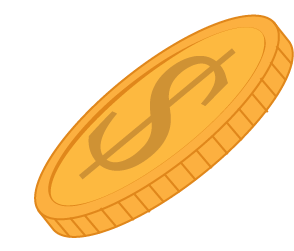  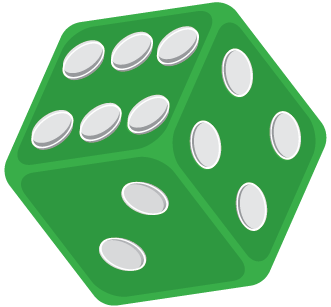

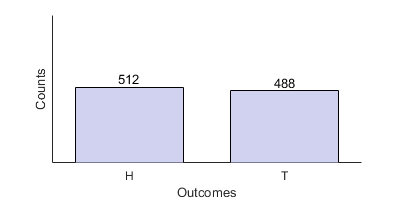

probEstimates =     0.5120    0.4880


randomExperiment = "coin";
trials           = 1000;
 
figure("Position",[0 0 400 200])
probEstimates = runExperiment(randomExperiment,trials)

  **Try**

- Use the first drop-down to set the random experiment to `"toss a coin"`. Use the second drop-down to set number of trials to 10. click **Run** to simulate the trials. Repeat 3-5 times.

- Set the random experiment to `"toss a coin"`. Start with `10` trials going up to `100000`. Each time, click **Run** to simulate the trials. Observe the values in `probEstimates`.

- Set the random experiment to `"roll a fair die"`. Start with `10` trials going up to `100000`. Each time, click **Run** to simulate the trials. Observe the values in `probEstimates`.

 ***Reflect***

- *Based on the classical definition of probability, what do you expect the probabilities of the different outcomes for a fair coin toss and a fair die roll to be?*

- *What is the relationship between ten runs of the 1000-trial experiment and one run of the 10,000-trial experiment?*

- *How many trials does it take to consistently get the estimated probabilities consistent with your expectations?*

  **Try**

- Set `randomExperiment` to `"roll a weighted die"`. Set `trials` to an appropriate number to get a reasonable estimate of the probabilities. 

 ***Reflect***

- *Which numbers does the die seem to be weighted towards? Why do you think so?*

- *How many trials are sufficient to get a reliable estimate of the actual probability of any event? How do you know?*

- *Can you apply this method to estimate the probability that the S&P 500 index will go up by 2% tomorrow? If yes, how? If not, why not?*

### Axioms of Probability

Kolmogorov's three axioms provide a formal framework for probability, consistently unifying the classical, empirical, and subjective perspectives. The axioms are:

- $P\left(E\right)\ge 0$                           The probability of an allowable event $E$ is a non-negative real number. 

- $P\left(S\right)=1$                            The probability of the occurenence of at least one elementary event is 1. An elementary event is a single-outcome event. The *sample space *$S$ is the set of all possible elementary events of the random process.

- $P(\bigcup\limits_{i=1}^{\infty} E_{i})$ = $\sum_{i=1}^{\infty } P\left(E_i \right)$       The probability of a union of disjoint events is the sum of the probabilities of the individual events. Union implies the occurence of any one of the events. Disjoint events are those that cannot occur at the same time.

**Example.** Consider a single coin toss event. We can assume that the coin will either land on heads ($H$) or on tails ($T$). The axioms imply the following:

- The probability of landing heads is a non-negative real number less than or equal to 1. Same is true for landing tails. $P\left(H\right)\le 1;\;\;\;P\left(T\right)\le 1$

- The probability of landing *neither* heads *nor* tails is 0. $P\left({\left\lbrace H,T\right\rbrace }^C \right)=0$

- The probability of landing *one of* heads *or* tails is 1. $P\left(\left\lbrace H,T\right\rbrace \right)=1$

- 
$$P\left(H\right)+P\left(T\right)=1$$


Note that we do not assume a fair coin in any of these implications.

 ***Reflect***

- *What does each of the above axioms imply for the random experiment of rolling a fair six-sided die?*

- *What does each of these terms mean within the context of probability: random, chance, experiment, process, trial, event, outcome, countable, equally likely, sample space, event space, mutually independent*

## Helper Functions

function visualizeCards(randomDrawResult,probability,graphFlag)
% VISUALIZECARDS evaluates the probability of drawing a single card from 
% a deck of playing cards for a given random draw event RANDOMDRAWRESULT. 
% The function verifies the input probability PROBABILITY against the 
% classical definition of probability of the chosen event. 
% GRAPHFLAG is a logical input value that determines whether the function 
% plots a visualization of all the outcomes and favorable outcomes.

% Initialize variables for the graphic.
M = zeros(4,13);
cards = split("A " + num2str(2:10) + " J Q K")';
suits = ["♠";"♣";"♦";"♥"];
S = repmat(cards,4,1) + suits;
map = [0.95 0.95 0.95; 0.8 1 0.8];

% Update the index matrix based on the favorable outcomes for the selected
% event.
switch randomDrawResult
    case "AceClubs"
        M(2,1) = 1;
    case "King"
        M(:,13) = 1;
    case "Hearts"
        M(4,:) = 1;
    case "Black"
        M(1:2,:) = 1;
    case "BlackNum"
        M(3:4,2:10) = 1;
    case "Num"
        M(1:4,2:10) = 1;
    case "BlackOrQueen"
        M(1:2,:) = 1;
        M(:,12) = 1;
    case "RedJack"
        M(3:4,11) = 1;
end

% Calculate the probablity and generate strings for title and messages.
prob = nnz(M)/52;
if probability >= 1
    colorStr = "\color{red}";
    titleStr = "Probability cannot be greater than 1.";
elseif ~isnan(probability) && probability < 1
    if abs(probability-prob) <= 1e-3
        colorStr = "\color{blue}";
        titleStr = "Correct! P(" + randomDrawResult +") = " + nnz(M) + "/52 = " + nnz(M)/52;
    else
        colorStr = "\color{orange}";
        titleStr = "Verify the number of favorable outcomes for the selected event, and update favorableOutcomes";
    end
else
    return;
end

% Plot the graphic or simply plot plain text depending on the checkbox setting of graphFlag.
if graphFlag
    figure("Position",[0 0 1000 300])
    viewDeckOutcomes(M,map,S);
    title(colorStr + titleStr);
else
    figure("Position",[0 0 1000 40])
    text(0.1,0.2,colorStr + titleStr + newline + "Enable showGraphic to verify visually.")
    axis off
end

end

function I = viewDeckOutcomes(M,map,S)
% VIEWDECKOUTCOMES(M,MAP,S) displays a scaled image
% using the indices in matrix M and the colormap MAP.
% S is a matrix containing values to be printed inside each cell.
% The visualization labels and colors are optimized to display outcomes for
% drawing from a deck of cards.

% Generate the x and y coordinates for the center of the cells (from 1 to N).
[N1,N2] = size(M);
x = repmat(1:N2,N1,1);
y = repmat(1:N1,N2,1)';

% Plot the input matrix as an indexed image with a color map (M,MAP).
I = imagesc(M);
colormap(map)
caxis([0 2])

% Overlay the image with cards matrix (S).
hcolors = repmat([{[0 0 0]};{[0 0 0]};{[1 0 0]};{[1 0 0]}],N2,1);
gtext = text(x(:),y(:),S,"HorizontalAlignment","Center","FontSize",12);
set(gtext,{'Color'},hcolors)

% Set the axes properties for readability.
ax = gca;
ax.FontSize = 10;
ax.FontWeight = "bold";
ax.TickLength = [0 0];
ax.XAxis.MinorTickValues = 0.5:1:N2;
ax.YAxis.MinorTickValues = 0.5:1:N1;
ax.MinorGridLineStyle = "-";
grid on
grid minor
ax.GridLineStyle = "none";
ax.TitleFontSizeMultiplier = 1;
xticks([])
yticks([])
end

function probEstimates = runExperiment(randomProcess,trials)
% RUNEXPERIMENT(RANDOMPROCESS,REPEAT) generates random outcomes for the selected random process (RANDOMPROCESS) and for the
% number of times the experiment is repeated (REPEAT).

if randomProcess == "coin"
    NOut = 2;
    samples = unidrnd(NOut,trials,1);                               % Uniform distribution for a fair coin with 2 possible outcomes
    out = categorical(samples,1:NOut,["H","T"]);                    % Outcomes of all trials
elseif randomProcess == "fairdie"
    NOut = 6;
    weights = ones(1,NOut)./NOut;                             
    samples = randsample(1:NOut,trials,true,weights);               % Uniformly weighted distribution for a fair die with 6 possible outcomes
    out = categorical(samples,1:NOut);                              % Outcomes of all trials
elseif randomProcess == "unfairdie" 
    NOut = 6;
    weights = [0.15 0.15 0.15 0.18 0.18 0.19];
    samples = randsample(1:NOut,trials,true,weights);               % Weighted distribution for a weighted die with 6 possible outcomes
    out = categorical(samples,1:NOut);                              % Outcomes of all trials
end

% Animate a histogram of experiment outcomes. 
H = histogram(out(1),"Normalization","count","BarWidth",0.7,"FaceColor",[0.7 0.7 0.9]);    % Initialize histogram by including the first outcome
x = 1:NOut;
y = H.Values;
T = text(x,y,string(y'),'vert','bottom','horiz','center'); 
ax = gca;
set(ax,"Box","off","TickLength",[0 0])                           % Format the axis appearance for aesthetics                               
set(ax,"YTick",[])                                               % Display counts on y-axis without exponents
ylim([0 ceil(2*trials/H.NumDisplayBins)])                        % Set limits for y-axis based on the number of experiments and number of bins
ylabel("Counts")
xlabel("Outcomes")
hold on
N = round(5.*trials.^0.3);                                       % Loop over all the experiment outcomes
for k = ceil(linspace(1,length(out),N))                          % Update histogram every few experiments depending on the number of times repeated to avoid long animation
    set(H,"Data",out(1:k));                                      % Update histogram data
    y = H.Values;
    set(T,{'String'},cellstr(string(y')))
    set(T,{'Position'},num2cell([x;y]',2))
    drawnow
end
hold off
probEstimates = H.Values./trials;
end